# Template of Manipulator Short project: Skull tumor surgery

**List of to do:**

The Robotic environment must contain:

1.-  **Taula d'operacions: **L'entorn de treball está compost per una** taula principal** de dimensions 0.6 x 1.8 m on es col·loca al pacient  i una **taula auxiliar** de 50cmx50cm on hi estarà el Puma. Per defecte la taula principal esta inclinada 30º y la taula auxiliar sempre esta connectada a l'extrem superior.

Dimensions inicials de les taules

mainTableW = 1; % amplada de la taula pricipal
mainTableH = 2; % llargada de la taula pricipal
auxTableW = 0.5; % amplada de la taula auxiliar
auxTableH = 0.5; % llargada de la taula auxiliar

Parametres de posició inicial. En aquest cas, considerarem que 

mainTablePositionX = 3;
mainTablePositionY = 3;
mainTablePositionZ = 3; % elevació de la taula principal
mainTableTilingDegrees = 15;
mainTableTilingZOffset = mainTableH * tan(deg2rad(mainTableTilingDegrees));
mainTablePosition = [mainTablePositionX mainTablePositionY mainTablePositionZ];

auxTableTilingDegrees = 0;
auxTableTilingZOffset = auxTableH * tan(deg2rad(auxTableTilingDegrees));
auxTableYOffset = (mainTableH/2)+auxTableH/2;
auxTablePosition = [0 auxTableYOffset mainTableTilingZOffset] + mainTablePosition;

mainTablePoints = getTablePointsMatrixFromCentre(mainTablePosition, mainTableW, mainTableH, mainTableTilingZOffset)

mainTablePoints =     2.5000    3.5000    3.5000    2.5000
    2.0000    2.0000    4.0000    4.0000
    3.0000    3.0000    3.5359    3.5359


auxTablePoints = getTablePointsMatrixFromCentre(auxTablePosition, auxTableW, auxTableH, auxTableTilingZOffset)

auxTablePoints =     2.7500    3.2500    3.2500    2.7500
    4.0000    4.0000    4.5000    4.5000
    3.5359    3.5359    3.5359    3.5359


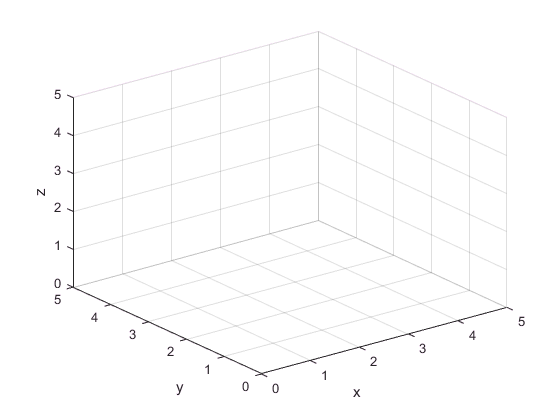

mainTableFigureId = 30;
auxTableFigureId = 40;
axis([0 5 0 5 0 5])
grid
xlabel('x')
ylabel('y')
zlabel('z')

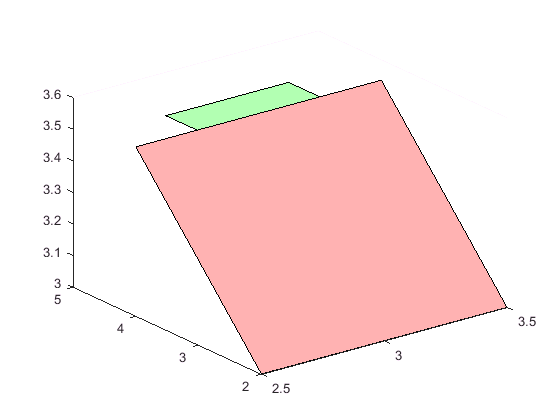

figure
drawTable(mainTablePoints, 'r');
hold on
drawTable(auxTablePoints, 'g');

2.- A 3D model of a human body on the operating table. Use the Workspace given, or other you might find.

*Add your comemnts here..... be concise*

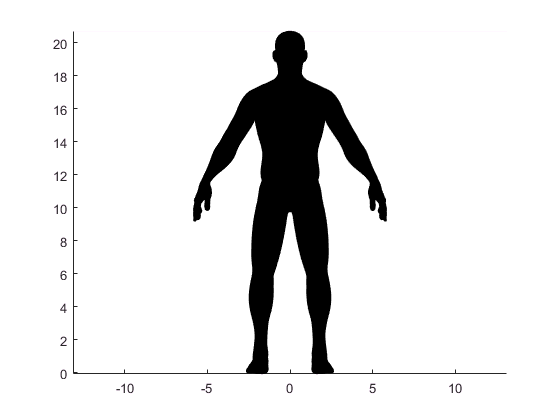

[V,F] = readOBJ('Human_body.obj','Quads',true);
 % Turn triangles into degenerate quads 

figure
axis equal;
patch('Faces',F,'Vertices',V);

3.- A human skull model, embedded in the head of the human. Place the fiducials.

*Add your comemnts here.....be concise*

%% put your code Here

4.- Use the Dicom images to get the points of the outer perimeter of the tumor relative to some reference frame located in the human skull.

*Add your comemnts here.....be concise*

%% put your code Here
X = [0 1 1 0];
Y = [0 0 1 1];
Z_0 = [0 0 0 0];
X = [0 1 1 0];
Y = [0 0 1 1];
Z_05 = [0.5 0.5 0.5 0.5];
X = [0 1 1 0];
Y = [0 0 1 1];
Z_1 = [1 1 1 1];
C = [0.5];

figure
axis ([-0.5 1.5 -0.5 1.5 -0.5 1.5])
hold on
% labelling
zlabel('z');ylabel('y');xlabel('x');
% Create title
title('Sckeching key ideas.');
%% drawing the figure
fill3(X,Y,Z_0,C);
fill3(X,Y,Z_05,C);
fill3(X,Y,Z_1,C);
alpha 0.2
view([-22.85 25.81])

*First approach:**  Asume that the ZX plane of the Robot is aligned with the plane of symmetry of the human body.*

5.- Display all necessary Reference Frames

*Add your comemnts here.....be concise*

%% put your code Here

6.- Place the 6R Robot manipulator nearby the operating table to warranty that the head is in the reachable work space. Use a Puma 560.

*Add your comemnts here.....be concise*

%% put your code Here

7.- Get the transformation that maps tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

8.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

9.- Prepare a script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

10.- Prepare a script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

11.- Prepare a script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

*Second approach:**  Assume that the ZX plane of the Robot is not aligned with plane of symetry of the human body and it is needed a orientation calibration.*

12.-Get the transformation that maps tumor points in Robot Frame. See teacher help: Triangle.mlx

*Add your comemnts here.....be concise*

%% put your code Here

13.- Print the tumor points in Robot Frame.

*Add your comemnts here.....be concise*

%% put your code Here

14.-Use the script that perform a biopsy. Zoom in the scene

*Add your comemnts here.....be concise*

%% put your code Here

15.- Use the  script that perform trepanation.

*Add your comemnts here.....be concise*

%% put your code Here

16.- Use the script that perform tumor burning with the laser.

*Add your comemnts here.....be concise*

%% put your code Here

## Auxiliar Functions

Funcions auxiliars

function drawTable(tablePointsMatrix,tableColor)
tablePolygonX = tablePointsMatrix(1,:);
tablePolygonY = tablePointsMatrix(2,:);
tablePolygonZ = tablePointsMatrix(3,:);
fill3(tablePolygonX,tablePolygonY,tablePolygonZ,tableColor);
alpha 0.3;
end
function tablePoints = getTablePointsMatrixFromCentre(centrePoint,tableWidth,tableHeigth,tilingOffset)
dx = tableWidth/2;
dy = tableHeigth/2;
dz = tilingOffset;
centrePointsAs4x3Matrix = repmat(centrePoint ,4,1);
tablePointsAs4x3Matrix = [-dx -dy 0;dx -dy 0; dx dy dz; -dx dy dz];
tablePointsFromCentre = centrePointsAs4x3Matrix + tablePointsAs4x3Matrix;
tablePoints = tablePointsFromCentre';
end